**Data**

x = [10    20    30    40    50    60    70    80    90   100]

x =     10    20    30    40    50    60    70    80    90   100


y = [0.18    0.29    0.32    0.39    0.40    0.41    0.43    0.47    0.47    0.47]

y =     0.1800    0.2900    0.3200    0.3900    0.4000    0.4100    0.4300    0.4700    0.4700    0.4700


**Plot data**

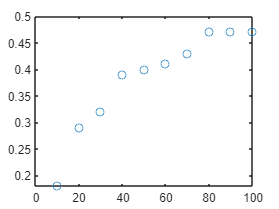

plot(x,y,'o')

**Transform data**

new_x = 1./x

new_x =     0.1000    0.0500    0.0333    0.0250    0.0200    0.0167    0.0143    0.0125    0.0111    0.0100


new_y = 1./y

new_y =     5.5556    3.4483    3.1250    2.5641    2.5000    2.4390    2.3256    2.1277    2.1277    2.1277


**Perform linear regression & plot dataset + fitted line**

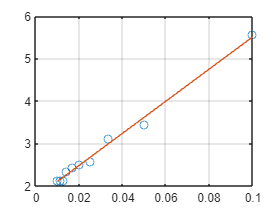

a =    37.8012    1.7269


r2 = 0.9922

[a,r2] = linregr(new_x,new_y)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 1/a(2)

alpha = 0.5791

beta = alpha*a(1)

beta = 21.8901

**Plot the original data with the best fit nonlinear curve**

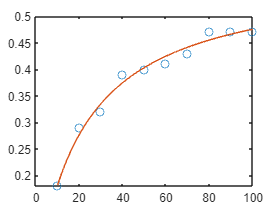

xx = 10:0.1:100 ;
yy = alpha * (xx ./ (beta + xx));
plot(x, y, 'o', xx, yy, '-')

**Predict the value of y for the given x**

xtest = 45

xtest = 45

predict_y = alpha * (xtest / (beta + xtest))

predict_y = 0.3896